addpath("C:\Users\roboime\Desktop\RoboIME Second Submission\")
clc;
clear;
close all;
pause(2);
rosIP = "192.168.187.128" 

rosIP = "192.168.187.128"

rosshutdown;

Shutting down global node /matlab_global_node_16901 with NodeURI http://192.168.187.1:49552/ and MasterURI http://192.168.187.128:11311.


pause(2);
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_04628 with NodeURI http://192.168.187.1:52331/ and MasterURI http://192.168.187.128:11311.


%Inicializa trajAct e gripAct
[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct');
trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = []; 
[gripAct, gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory', 'control_msgs/FollowJointTrajectory', 'DataFormat', 'struct');
gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];
waitForServer(gripAct);

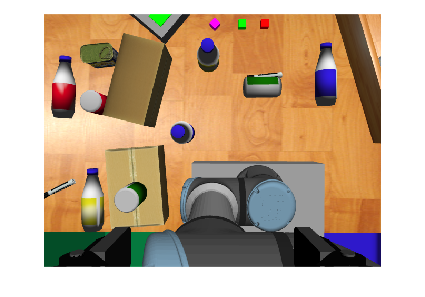

rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);
imshow(rgbImg);

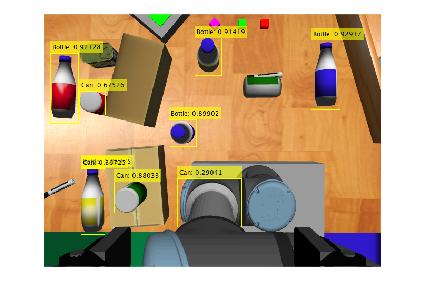

addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Color_Detector.mat','colorDetector'); 
imTest = rgbImg; 
[dbox,dscore,dlabel] = detect(colorDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

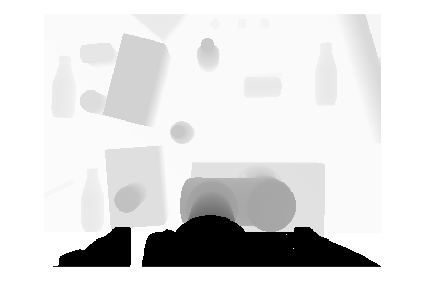

 pause(2); 
depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
depthMsg = receive(depthSub,3);
depthImg = rosReadImage(depthMsg);
imshow(depthImg);

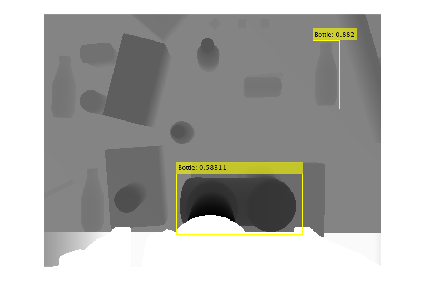




addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

pause(5);

% jointSub = rossubscriber("/joint_states",'DataFormat','struct')
% waitForServer(trajAct);
% modelSub = rossubscriber('/gazebo/model_states', 'gazebo_msgs/ModelStates');
% UR5e = loadrobot("universalUR5e", DataFormat = "struct");
% tform = UR5e.Bodies{3}.Joint.JointToParentTransform;
% UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));  
% tform = UR5e.Bodies{4}.Joint.JointToParentTransform;
% UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
% tform = UR5e.Bodies{7}.Joint.JointToParentTransform;
% UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));    
% % Cria resolvedor de cinemática inversa
% ik = inverseKinematics("RigidBodyTree", UR5e);
% rng(1);
% obstacles = Obstaculos(modelSub); %obstaculos file
% rrt = manipulatorRRT(UR5e, obstacles, ValidationDistance = 0.1, IgnoreSelfCollision=true );
% abrir_garra(0, gripGoal, gripAct);%abrir garra 
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-0.36 -0.01 0.45], [0.1 0.1 0 -.1 0 0]); %cinematica inversa

% plannedpath = plan(rrt, [0 0 0 0 0 0], goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal); %packTrajGoal
%     sendGoal(trajAct,trajGoal); 
% end
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-0.362 -0.01 0.23], [0.1 0.1 0 -.1 0 0]);
% 
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% pause(2);
% abrir_garra(0.205, gripGoal, gripAct); %abrir_garra e packGripGoal
% pause(6);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct);%ajuste
% goalconfig_trocado = ajuste(goalconfig_trocado, 3, .45, 2, jointSub, trajGoal, trajAct);
% pause(3);
% abrir_garra(0,gripGoal,gripAct);
% pause(3);
% disp('Último ponto planejado:')
% disp(rrtpath(end,:))

% 
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [.460 -.07 0.247], [0 .5 -.5 0 0 0]);
% plannedpath = plan(rrt, [0 0 0 0 0 0] , goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% abrir_garra(0.5153, gripGoal, gripAct);
% pause(5);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

% goalconfig_trocado = ajuste(goalconfig_trocado, 3, -2.3199 - goalconfig_trocado(3)+3.3, 4, jointSub, trajGoal, trajAct)
% pause(3);
% abrir_garra(0,gripGoal,gripAct);
% pause(5);
% goalconfig_trocado = rotelem([0 0 0 0 0 0], [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct); %rotelem
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [0.655 0.016 0.32], [0 .5 -.5 0 0 0])
% plannedpath = plan(rrt, [0 0 0 0 0 0] , goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end

% 
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [0.655 0.016 0.245], [0 .5 -.5 0 0 0]);
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% abrir_garra(0.2222, gripGoal, gripAct);
% pause(6);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

% lixo(1, trajGoal, trajAct, gripGoal, gripAct); %lixo e mover_para
% pause(3);

% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-.5 .265 .3], [1 -1 0 0 0 0]);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% pause(2);
% goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-.5 .265 .13], [1 -1 0 0 0 0])
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end

% abrir_garra(0.226, gripGoal, gripAct);
% pause(6);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct);
% lixo(1, trajGoal, trajAct, gripGoal, gripAct);
% pause(3);

% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.625 .28 .3], rrtpath(end,:));
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% pause(2);

% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.623 .3 .085], rrtpath(end,:));
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end

% abrir_garra(.22, gripGoal, gripAct);
% pause(5);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct)
% lixo(2,trajGoal, trajAct,gripGoal, gripAct);
% pause(3);

% goalconfig_trocado = rotelem([0 0 0 0 0 0], [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct);

% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.525 -.09 .3], [-.1 .1 0 0 0 0]);
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% 
% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.525 -.06 .09], [-.1 .1 0 0 0 0]);
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end

% abrir_garra(.212, gripGoal, gripAct);
% pause(5);
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)
% lixo(2,trajGoal, trajAct,gripGoal, gripAct);
% pause(3);

% abrir_garra(1, gripGoal, gripAct);
% pause(5);
% abrir_garra(0, gripGoal, gripAct);
% pause(2);

% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [.687 -.085 .4], [-.1 .1 0 0 0 0]);
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end
% goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [.687 -.085 .14], [-.1 .1 0 0 0 0]);
% pause(3);
% plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
% shortenedPath = shorten(rrt,plannedpath,40);
% rrtpath = interpolate(rrt,shortenedPath,10);
% for i = 1:size(rrtpath, 1)
%     trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
%     sendGoal(trajAct,trajGoal); 
% end

% abrir_garra(0.62, gripGoal, gripAct);
% pause(5);

% 
% goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)
% lixo(1,trajGoal, trajAct,gripGoal, gripAct);
% pause(3);